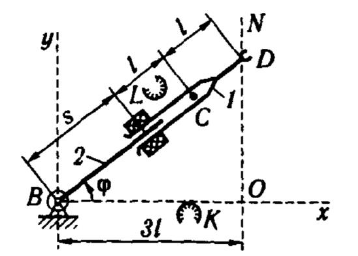

ASSUME ANOTHER REFERNCE LIKE :

m1 = 2 kg (B - center mass)

m2 = 2 kg (C - center mass)

I1 = 2 kg*m^2

I2 = 1 kg*m^2

L = 0.2 m

clear all
syms q1 q2 dq1 dq2 ddq1 ddq2 l d1 d2 m1 m2 I1 I2 g real

% forward kinematics
FK= Rz(q1) * Tx(q2) * Tx(2*l)

$$FK = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 2\,l\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 2\,l\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% first get joints origins & center of mass locations  
O0 = [0 0 0]'

O0 =      0
     0
     0


O1 = [0 0 0]'

O1 =      0
     0
     0


O2 = [q2*cos(q1) q2*sin(q1) 0]'

$$O2 = \left(\begin{array}{c} q_{2}\,\cos\left(q_{1}\right)\\ q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

Oc1 = [0 0 0]'

Oc1 =      0
     0
     0


Oc2 = [(q2+l)*cos(q1) (q2+l)*sin(q1)  0 ]'

$$Oc2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ \sin\left(q_{1}\right)\,\left(l+q_{2}\right)\\ 0 \end{array}\right)$$

% second get the z from tf 
Z0 = [0 0 1]'

Z0 =      0
     0
     1


Z1 = [cos(q1) sin(q1) 0]'

$$Z1 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ \sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

## Jacobians

1- linear  velocity

2- angular velocity

## calculate the linear velocity

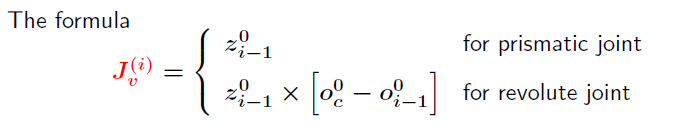

% third compute Jv for the joints
Zer = [0 0 0]';
% Jv1
Jv1 = [cross(Z0,(Oc1-O0)), Zer]

Jv1 =      0     0
     0     0
     0     0


% Jv2
Jv2 = [cross(Z0,(Oc2-O0)), Z1]

$$Jv2 = \left(\begin{array}{cc} -\sin\left(q_{1}\right)\,\left(l+q_{2}\right) & \cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\left(l+q_{2}\right) & \sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

## calculate the angular velocity

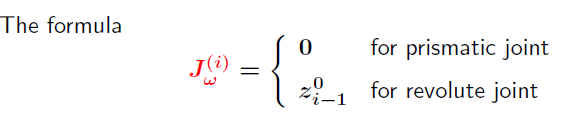

% fourth compute  Jw for  the joints
% Jw1
Jw1 = [Z0, Zer]

Jw1 =      0     0
     0     0
     1     0


% Jw2
Jw2 = [Z0 ,Zer]

Jw2 =      0     0
     0     0
     1     0


## matrix for rotation

%Fifth extract the rotation matrices
R1 = [ cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]

$$R1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = [ cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]

$$R2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

# Kinetic energy

%sixth compute the kinetic Energy
q = [q1;q2];
D1 = (m1*Jv1')*Jv1 + Jw1'*R1*I1*R1'*Jw1 %kinect energy of link 1

$$D1 = \left(\begin{array}{cc} I_{1} & 0\\ 0 & 0 \end{array}\right)$$

D2 = (m2*Jv2')*Jv2 + Jw2'*R2*I2*R2'*Jw2 %kinect energy of link 2

$$D2 = \left(\begin{array}{cc} I_{2}+m_{2}\,{\cos\left(q_{1}\right)}^{2}\,{\left(l+q_{2}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2}\,{\left(l+q_{2}\right)}^{2} & 0\\ 0 & m_{2}\,{\cos\left(q_{1}\right)}^{2}+m_{2}\,{\sin\left(q_{1}\right)}^{2} \end{array}\right)$$

D=D1+D2;  %The kinetic energy of the system
D=simplify(D)

$$D = \left(\begin{array}{cc} m_{2}\,l^{2}+2\,m_{2}\,l\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

## Potential energy

%seventh compute the Potential Energy
P1 = 0;  
P2 = m2*g*(l+q2)*sin(q1);
P = P1+P2;  % The potential energy of the system
G1 = diff(P, q1)

$$G1 = g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)$$

G2 = diff(P, q2)

$$G2 = g\,m_{2}\,\sin\left(q_{1}\right)$$

G = [G1; G2]

$$G = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

## Calculating Corilos

%Eighth  define  Centrifugal and Coriolis terms
dq = [dq1; dq2];
ddq = [ddq1; ddq2];
C = Coriolis(D,q,dq,2);
C=simplify(C)

$$C = \left(\begin{array}{cc} {\mathrm{dq}}_{2}\,m_{2}\,\left(l+q_{2}\right) & {\mathrm{dq}}_{1}\,m_{2}\,\left(l+q_{2}\right)\\ -{\mathrm{dq}}_{1}\,m_{2}\,\left(l+q_{2}\right) & 0 \end{array}\right)$$

## the equations of motion take the matrix form

tor1 = D

$$tor1 = \left(\begin{array}{cc} m_{2}\,l^{2}+2\,m_{2}\,l\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

tor2 =C*dq

$$tor2 = \left(\begin{array}{c} 2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(l+q_{2}\right)\\ -{{\mathrm{dq}}_{1}}^{2}\,m_{2}\,\left(l+q_{2}\right) \end{array}\right)$$

tor3 = G

$$tor3 = \left(\begin{array}{c} g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)\\ g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

tor = D *ddq +C * dq + G

$$tor = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left(m_{2}\,l^{2}+2\,m_{2}\,l\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)+g\,m_{2}\,\cos\left(q_{1}\right)\,\left(l+q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,m_{2}\,\left(l+q_{2}\right)\\ -m_{2}\,\left(l+q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}+{\mathrm{ddq}}_{2}\,m_{2}+g\,m_{2}\,\sin\left(q_{1}\right) \end{array}\right)$$

D(q1,q2) = subs(D,{m1, m2, I1, I2, l},{2 2 2 1 0.2})

$$D(q1, q2) = \left(\begin{array}{cc} 2\,{q_{2}}^{2}+\frac{4\,q_{2}}{5}+\frac{77}{25} & 0\\ 0 & 2 \end{array}\right)$$

%C(q1,q2,dq1,dq2) = subs(C ,{m1, m2, I1, I2, l},{2 2 2 1 0.2})

C(q1,q2,dq1,dq2) = subs(C*dq ,{m1, m2, I1, I2, l},{2 2 2 1 0.2})

$$C(q1, q2, dq1, dq2) = \left(\begin{array}{c} 4\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\left(q_{2}+\frac{1}{5}\right)\\ -2\,{{\mathrm{dq}}_{1}}^{2}\,\left(q_{2}+\frac{1}{5}\right) \end{array}\right)$$

G(q1,q2) = subs(G ,{m1, m2, I1, I2, l, g},{2 2 2 1 0.2 9.81})

$$G(q1, q2) = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}\right)\,\left(q_{2}+\frac{1}{5}\right)}{50}\\ \frac{981\,\sin\left(q_{1}\right)}{50} \end{array}\right)$$

## Applying force & torque  then Plotting to find position & velocity & acceleration

q_1_0 = pi/2;
q_2_0 = 0;
dq_1_0 = 0;
dq_2_0 = 0;
ddq_1_0 = 0 ;
ddq_2_0 = 0 ;
delta_t=0.01;
U = [500;750]; %force and torque
n=300;
q1p=zeros(1,n);
q2p=zeros(1,n);
dq1p=zeros(1,n);
dq2p = zeros(1,n);
ddq1p = zeros(1,n);
ddq2p = zeros (1,n);
for i = 1:n
 q1p(i)=q_1_0;
 q2p(i)=q_2_0;
 dq1p(i)=dq_1_0;
 dq2p(i)=dq_2_0;
 ddq1p(i)=ddq_1_0;
 ddq2p(i)=ddq_2_0;
 % inv(A) * b = A\b
 ddq = (D(q_1_0, q_2_0))\(U-C(q_1_0, q_2_0,dq_1_0,dq_2_0)-G(q_1_0,q_2_0));

 dq_1_0=dq1p(i) + double(ddq(1)*delta_t);
 dq_2_0=dq2p(i) + double(ddq(2)*delta_t);
 
 ddq_1_0=double(ddq(1));
 ddq_2_0=double(ddq(2));
 
 q_1_0 = q1p(i) + dq_1_0*delta_t;
 q_2_0 = q2p(i) + dq_2_0*delta_t;
end
t = 0:0.1:(0.1*(n-1));
U1_vec = U(1) * (1:length(t));
U2_vec = U(2) * (1:length(t));

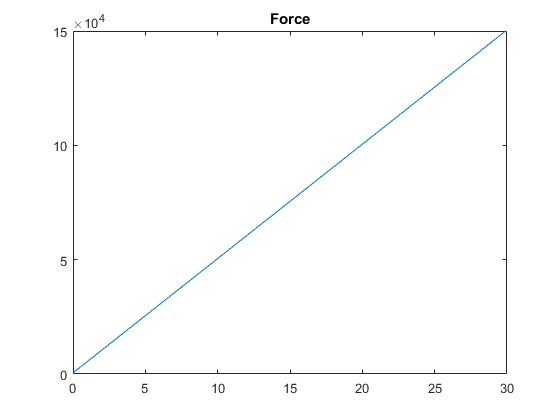

plot(t,U1_vec)
title('Force')

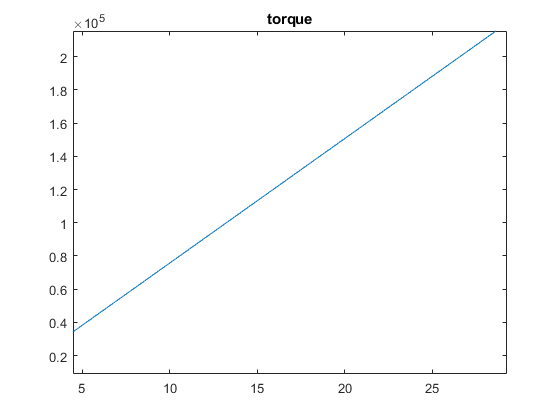

plot(t,U2_vec)
title('torque')

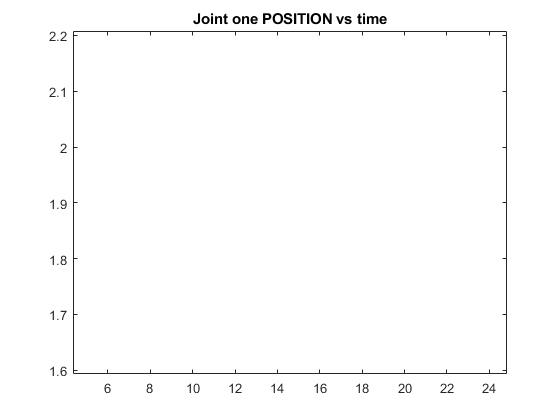

plot(t,q1p)
title('Joint one POSITION vs time')

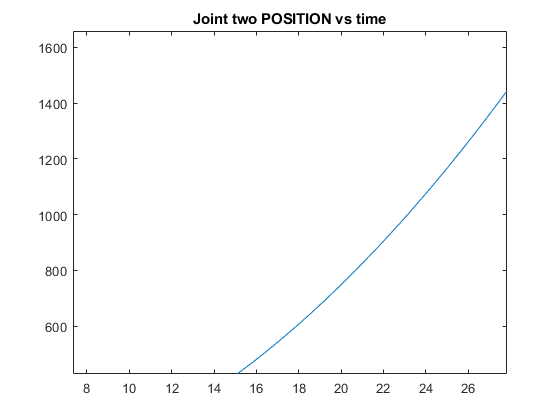

plot(t,q2p)
title('Joint two POSITION vs time')

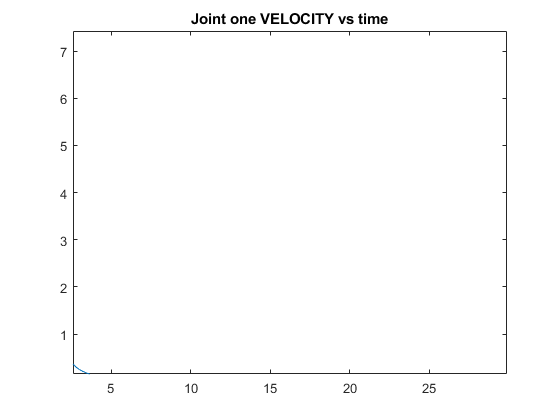

plot(t,dq1p)
title('Joint one VELOCITY vs time')

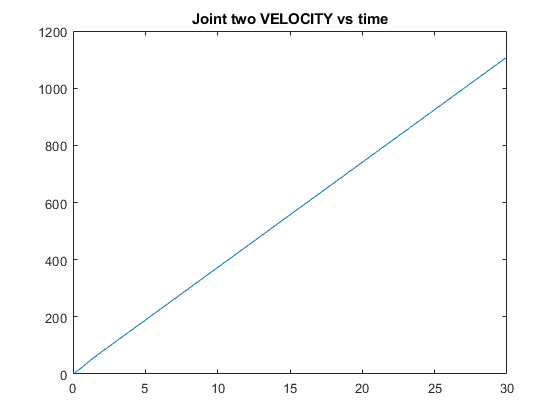

plot(t,dq2p)
title('Joint two VELOCITY vs time')

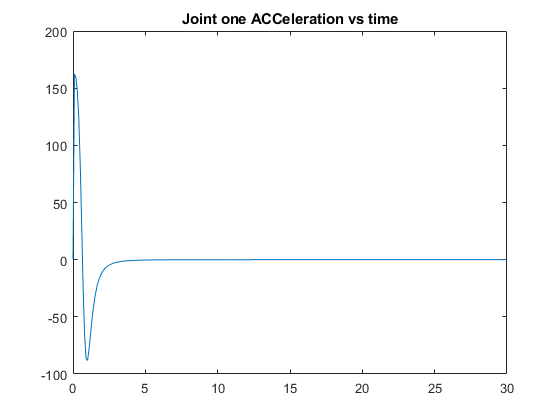

plot(t,ddq1p)
title('Joint one ACCeleration vs time')

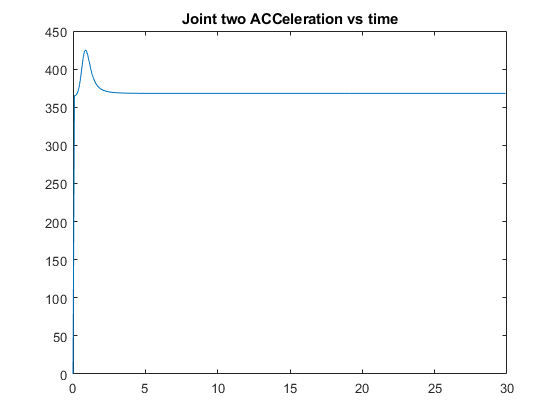

plot(t,ddq2p)
title('Joint two ACCeleration vs time')

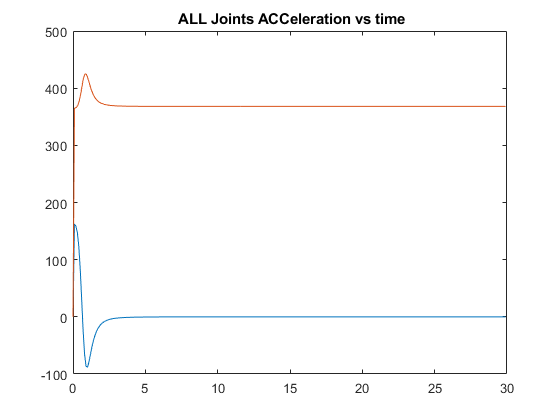

plot(t,ddq1p)
hold on 
plot(t,ddq2p)
title(' ALL Joints ACCeleration vs time')